% B=imread('flower.jpg');  
% B=rgb2gray(B);  
% doubleB=im2double(B);%  
% %read the image and store it as matrix B, convert the image to a grayscale  
% %photo and convert the image to a class 'double'  
% [U,S,V]=svd(doubleB);   
% C=S;  
% for N=[5,10,25,50,100]  
% C(N+1:end,:)=0;  
% C(:,N+1:end)=0;  
% D=U*C*V';  
% %Use singular value decomposition on the image doubleB, create a new matrix  
% %C (for Compression diagonal) and zero out all entries above N, (which in  
% %this case is 100). Then construct a new image, D, by using the new  
% %diagonal matrix C.  
% %imshow(D);  
% error=C-D;   
% end

buffer = 'Image output using 5 singular values'

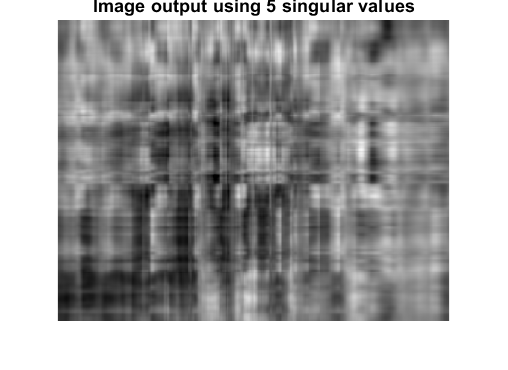

buffer = 'Image output using 30 singular values'

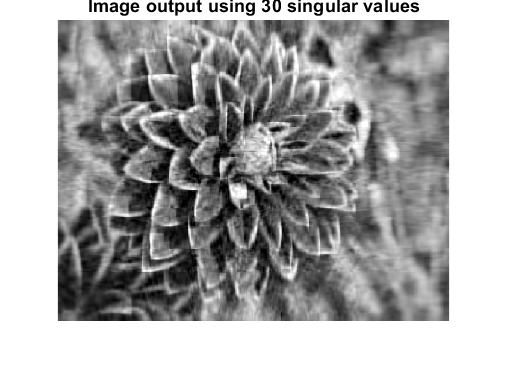

buffer = 'Image output using 55 singular values'

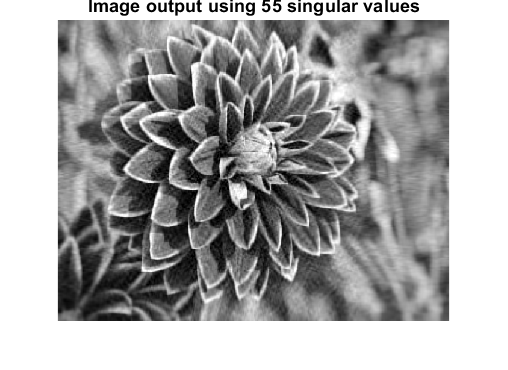

buffer = 'Image output using 80 singular values'

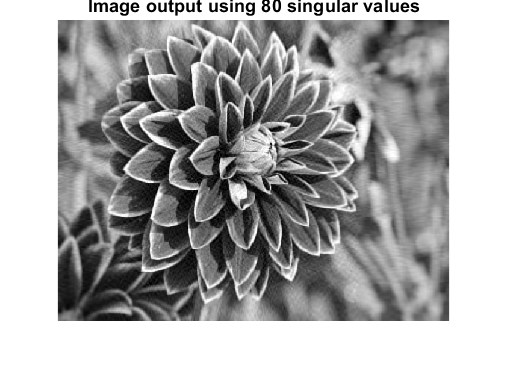

buffer = 'Image output using 105 singular values'

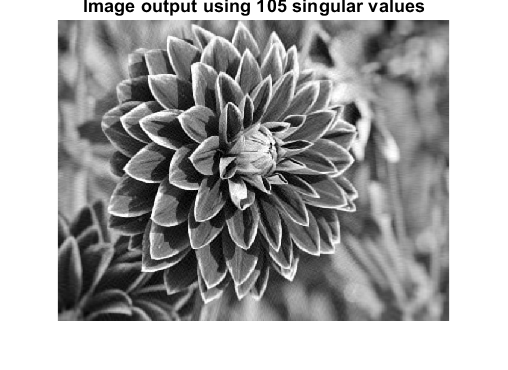

buffer = 'Image output using 130 singular values'

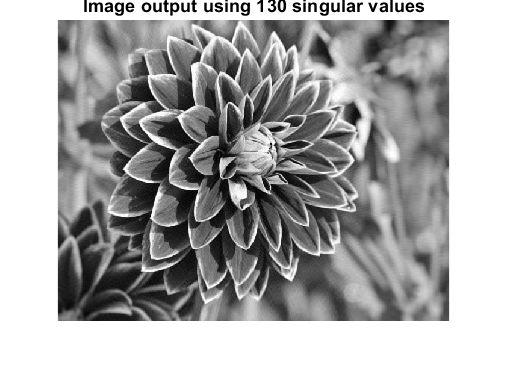

buffer = 'Image output using 155 singular values'

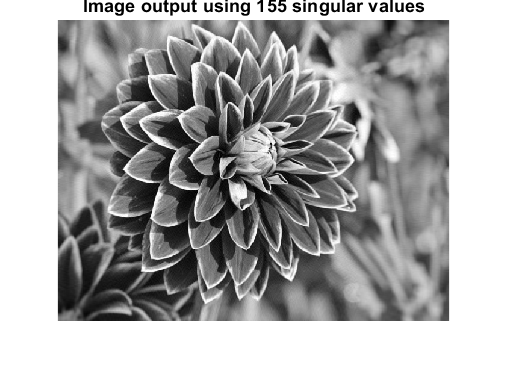

buffer = 'Image output using 180 singular values'

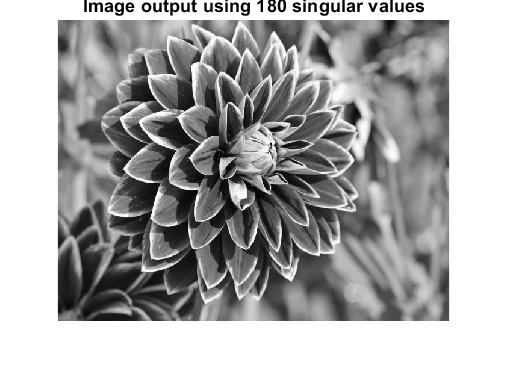

buffer = 'Image output using 205 singular values'

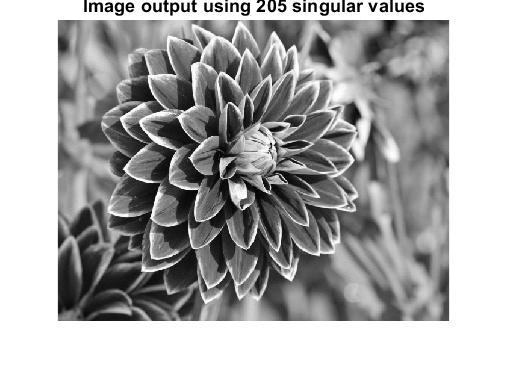

buffer = 'Image output using 230 singular values'

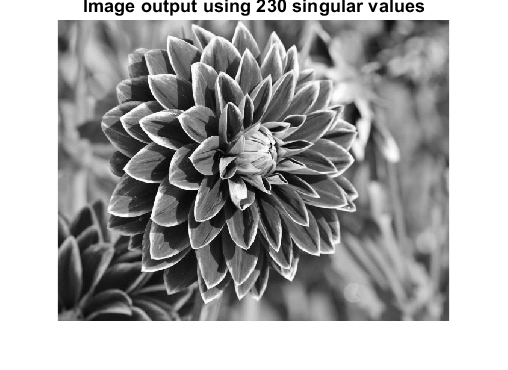

buffer = 'Image output using 255 singular values'

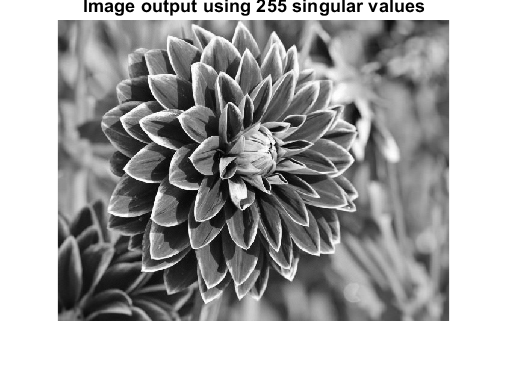

buffer = 'Image output using 280 singular values'

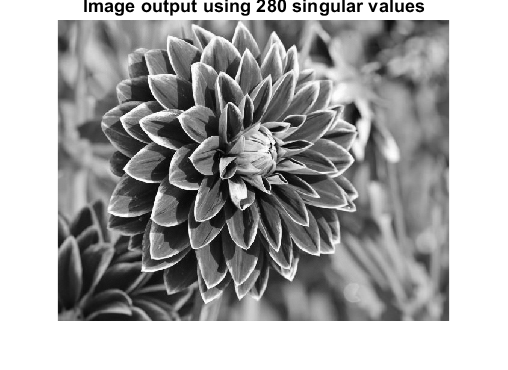

%reading and converting the image
inImage=imread("flower.jpg");
inImage=rgb2gray(inImage);
inImageD=double(inImage);

% decomposing the image using singular value decomposition
[U,S,V]=svd(inImageD);

% Using different number of singular values (diagonal of S) to compress and
% reconstruct the image
dispEr = [];
numSVals = [];
for N=5:25:300
    % store the singular values in a temporary var
    C = S;

    % discard the diagonal values not required for compression
    C(N+1:end,:)=0;
    C(:,N+1:end)=0;

    % Construct an Image using the selected singular values
    D=U*C*V';


    % display and compute error
    figure;
    buffer = sprintf('Image output using %d singular values', N)
    imshow(uint8(D));
    title(buffer);
    error=sum(sum((inImageD-D).^2));

    % store vals for display
    dispEr = [dispEr; error];
    numSVals = [numSVals; N];
end

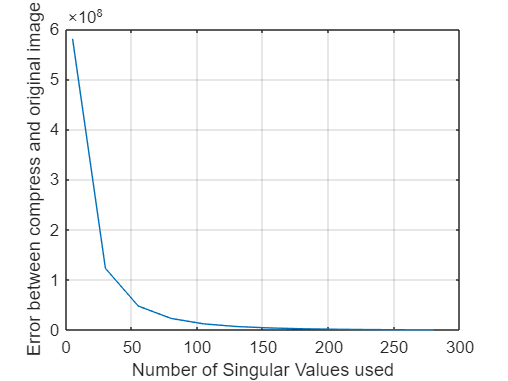


% dislay the error graph
figure; 
title('Error in compression');
plot(numSVals, dispEr);
grid on
xlabel('Number of Singular Values used');
ylabel('Error between compress and original image');

% Lena = double(imread('flower.jpg'));
% 
% % perform SVD on Lena
% [U,S,V] = svd(Lena);
% 
% % extract singular values
% singvals = diag(S);
% 
% % find out where to truncate the U, S, V matrices
% indices = find(singvals >= 0.01 * singvals(1));
% 
% % reduce SVD matrices
% U_red = U(:,indices);
% S_red = S(indices,indices);
% V_red = V(:,indices);
% 
% % construct low-rank approximation of Lena
% Lena_red = U_red * S_red * V_red';
% 
% % print results to command window
% r = num2str(length(indices));
% m = num2str(length(singvals));
% disp(['Low-rank approximation used ',r,' of ',m,' singular values']);
% 
% % save reduced Lena
% imwrite(uint8(Lena_red),'Reduced Lena.bmp');